Examen sisdin 2023 parte no lineales

## Apartado a)

syms x1 x2 e real
%Defino el fokin sistema
f(1, 1) = x2;
f(2, 1) = x1 + e*x1^2;
f

$$f = \left(\begin{array}{c} x_{2}\\ e\,{x_{1}}^{2}+x_{1} \end{array}\right)$$

%Calculo puntos de equilibrio. Como ya sé que para que haya equilibrio x2 =
%0 necesariamente, solo necesito encontrar los ceros de la segunda ecuación
solve(f(2, 1))

$$ans = \left(\begin{array}{c} 0\\ -\frac{1}{e} \end{array}\right)$$

Luego los puntos de equilibrio serán los puntos (0 0) y (-1/e 0)

p1 = [0; 0];
p2 = [-1/e; 0];

## Apartado b)

%Linealizo para [0 0] y el otro punto
J = jacobian(f, [x1 x2]);
%saco los autovalores
E = eig(J)

$$E = \left(\begin{array}{c} -\sqrt{2\,e\,x_{1}+1}\\ \sqrt{2\,e\,x_{1}+1} \end{array}\right)$$

%Y ahora los evalúo en los puntos de equilibrio
E00 = subs(E, {x1; x2}, {p1}) %En 00

$$E00 = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

Ee0 = subs(E, {x1; x2}, {p2}) %En e0

$$Ee0 = \left(\begin{array}{c} -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

Esto corresponde a un punto de silla para (0 0) y a un centro (parte real 0) para el punto (-1/e 0). Cabe esperar que la derivada de Lie de los sistemas linealizados sea 0 para múltiples valores de x1 y x2, luego no se podrá concluir gran cosa del test de Lyapunov. 

## Apartado c

Es evidente que para $\epsilon = 0$ este segundo punto de equlibrio se va a infinito o, lo que es lo mismo, desaparece y el sistema es inestable. Pero en las proximades de 0 el lío está servido, en el sentido de que altera la región en que el sistema es marginalmente estable. De hecho, en la medida que hacemos crecer $\epsilon$ vamos disminuyendo, más y más la region de estabilidad del centro, porque tiende a colapsar con el punto de silla situado en (0,0). El único efecto que tiene cambiar de signo $\epsilon$ es cambiar a qué lado den origen se sitúa el punto de equilibrio correspondiente al centro.

## Apartado d

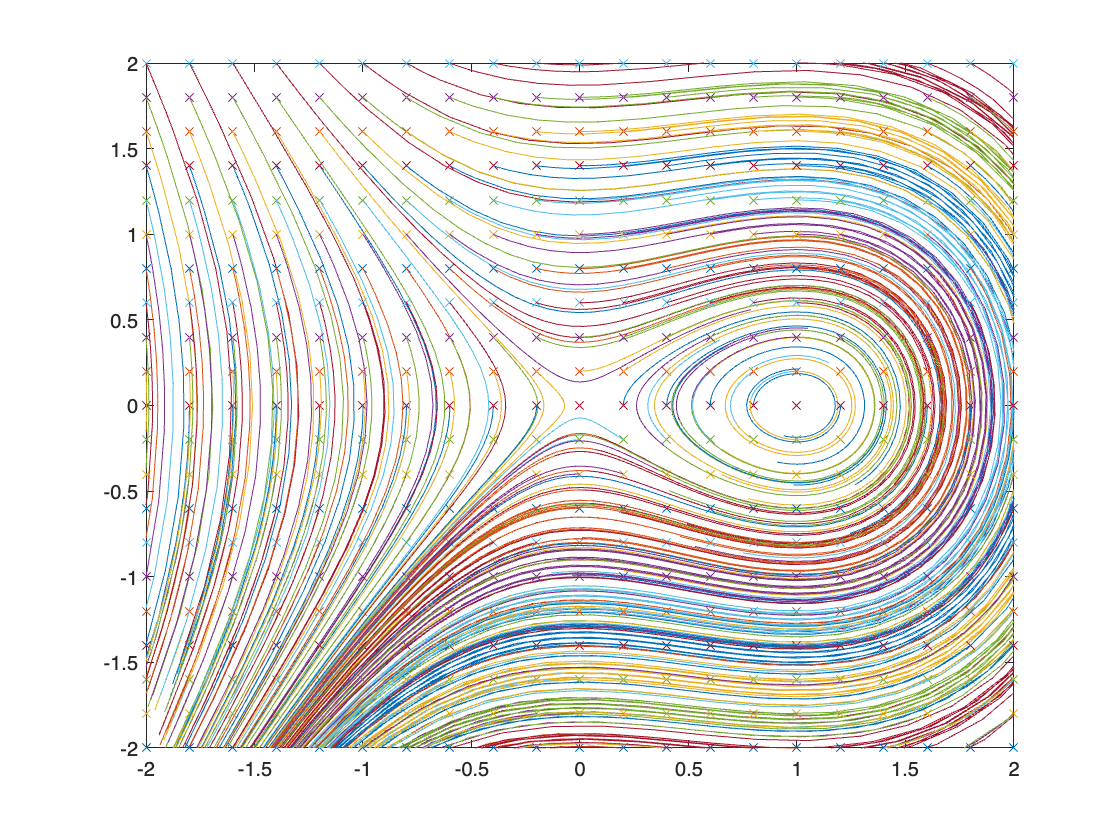

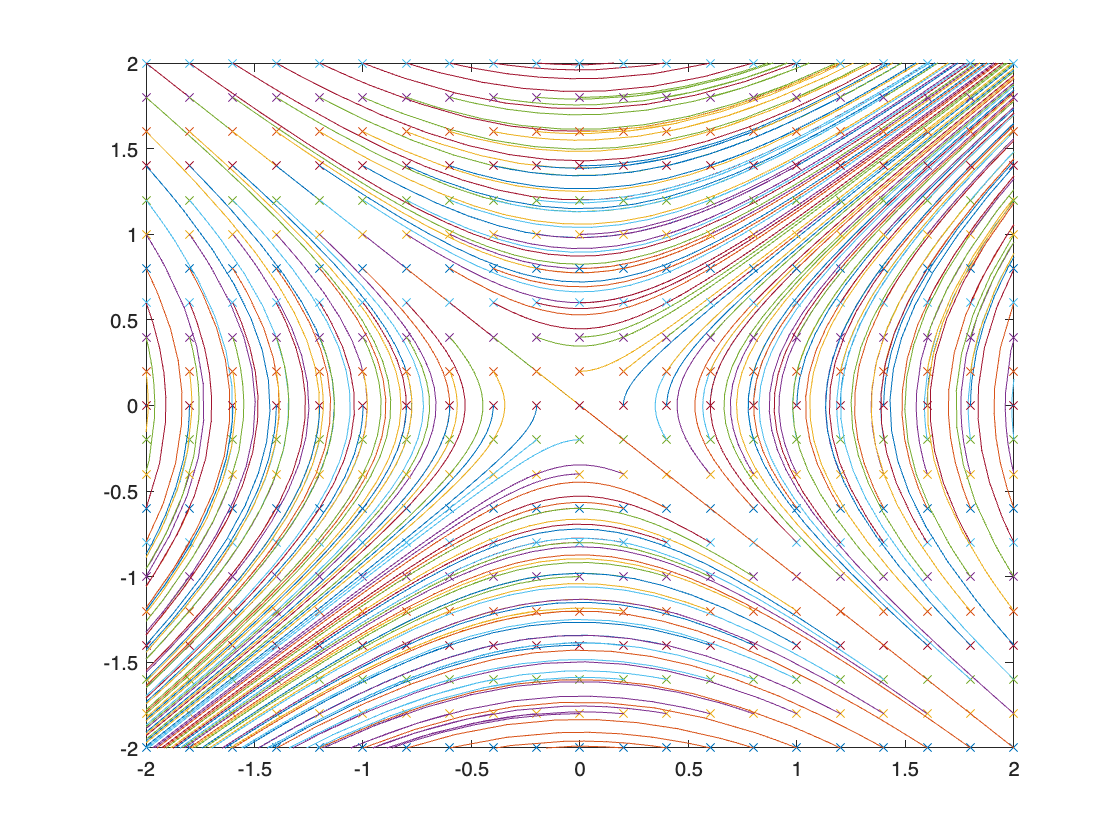

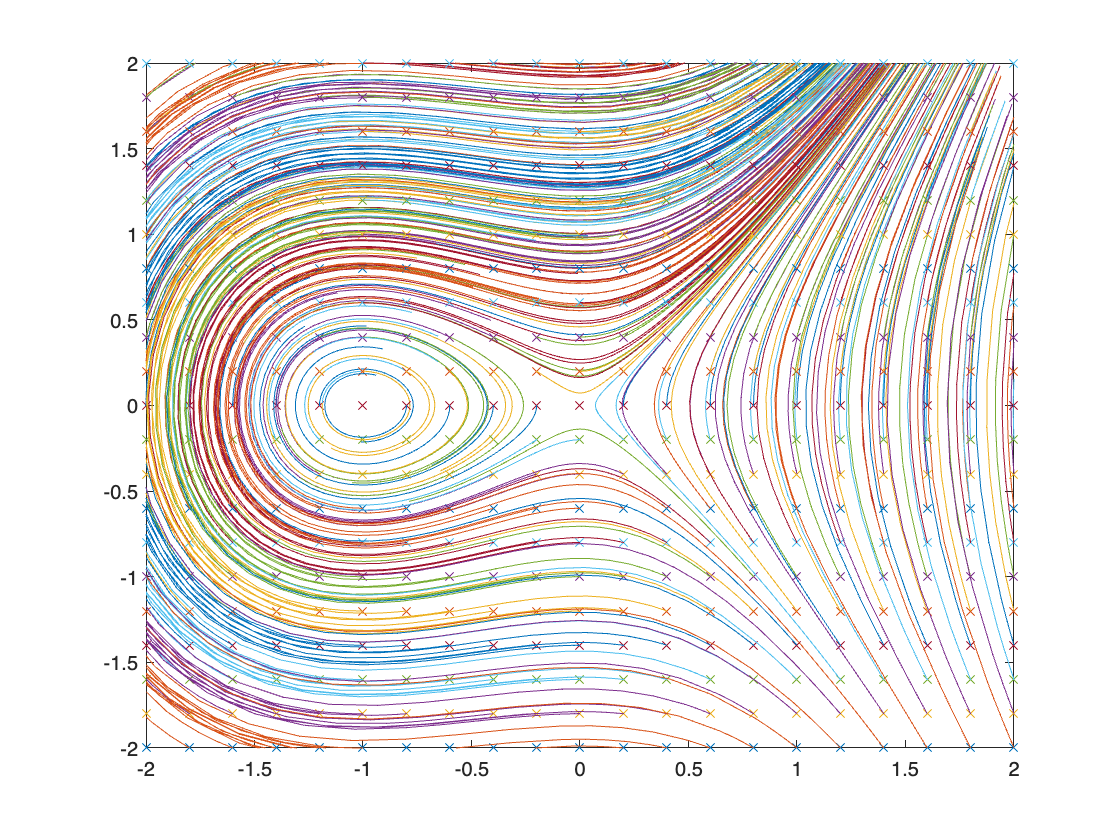

for eps = -1:1:1 %epsilon -1 0 1
    figure;
    for i = -2:0.2:2
        for j = -2:0.2:2
            plot(i, j, "x"); hold on;
            [t, x] = ode45(@(t, x)sys(t, x, eps), [0 5], [i;j]);
            plot(x(:, 1), x(:, 2))
        end
    end
    xlim([-2 2]);
    ylim([-2 2]);
    t = sprintf("\epsilon = %d", eps);
    title(t);
    hold off;
end 

function xdot = sys(t, x, eps)
    xdot(1, 1) = x(2, 1);
    xdot(2, 1) = x(1, 1) + eps*x(1, 1)^2;
end